
%% Load ideal signal
load('/MATLAB Drive/BSP_assignment2/Weiner filtering/idealECG.mat');  % should load yi (ideal ECG), optionally Fs
if ~exist('Fs','var') || isempty(Fs)
    Fs = 500; % Hz
end
yi = idealECG(:);                 % ensure column
N  = length(yi);
t  = (0:N-1).' / Fs;

%% Build noisy input x(n) = yi + eta
% White Gaussian noise such that SNR(yi vs eta_wg) = 10 dB
%eta_wg    = sqrt(Pwgn_need) * randn(N,1);
eta_wg    = yi - awgn(yi, 10,'measured')

eta_wg =    -0.0017
    0.0521
   -0.0161
    0.1562
    0.0133
   -0.0424
   -0.0090
    0.0680
    0.0649
   -0.1777
   -0.0939
   -0.0788
   -0.0123
   -0.0109
    0.0117


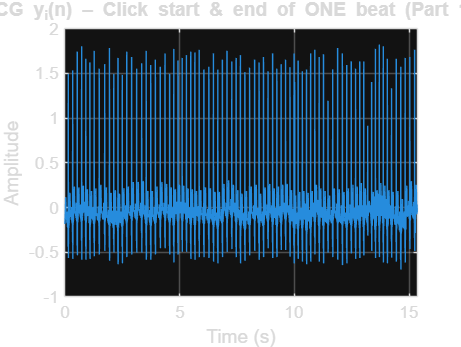


% 50 Hz sinusoid of amplitude 0.2
eta50     = 0.2 * sin(2*pi*50*(0:N-1)'/Fs);
eta100     = 0.2 * sin(2*pi*100*(0:N-1)'/Fs);
% Halfway index
thalf = floor(length(t)/2);
% Construct piecewise noise
eta = [eta_wg(1:thalf) + eta50(1:thalf);
           eta_wg(thalf+1:end) + eta100(thalf+1:end)];
x         = yi + eta;

%% Visualize raw signals and pick segments
figure('Name','Pick segments','Color','w'); 
plot(t, yi); grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('ideal ECG y_i(n) – Click start & end of ONE beat (Part 1 desired)');


% Pick one beat in yi
disp('Select START and END of a single beat in y_i(n) …');

Select START and END of a single beat in y_i(n) …


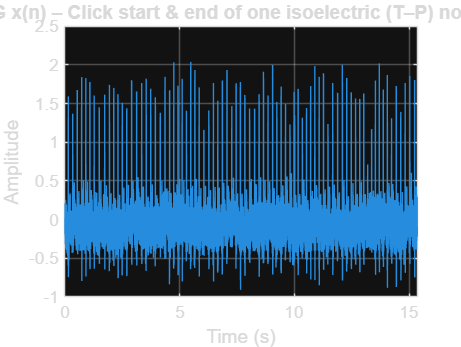

tStart = 4.496;   % start at 2s
tEnd   = 4.65;   % end at 3s
idxBeat = round(tStart*Fs) : round(tEnd*Fs);
y_desired_part1 = yi(idxBeat);
tBeat = t(idxBeat);

if idxBeat(1) == idxBeat(end)
    warning('You selected a single point — please select a wider range.');
end

figure('Name','Pick segments','Color','w');
plot(t, x); grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('noisy ECG x(n) – Click start & end of one isoelectric (T–P) noise segment');


% Pick one isoelectric noise segment in x
disp('Select START and END of an isoelectric (T–P) segment in x(n) …');

Select START and END of an isoelectric (T–P) segment in x(n) …


tStart = 4.814;   % start at 2s
tEnd   = 4.86;   % end at 3s
idxNoise = round(tStart*Fs) : round(tEnd*Fs);
n_seg    = x(idxNoise);      % noise-dominant segment (assumes minimal underlying ECG)
tNoise   = t(idxNoise);

Nfft = length(x);   % Use full length of signal
Xf = fft(x, Nfft);
Yf = fft(y_desired_part1, Nfft);   % Desired template
Nf = fft(n_seg, Nfft);             % Noise segment

Sxx = abs(Xf).^2;
Syy = abs(Yf).^2;
Snn = abs(Nf).^2;

Wf = Syy ./ (Syy + Snn);    % Wiener filter transfer function
Yhat_f = Wf .* Xf;           % Apply filter in frequency domain
y_hat = real(ifft(Yhat_f));  % Back to time domain

MSE_part1 = mean((yi - y_hat).^2);
fprintf('MSE (Part 1, Frequency-domain Wiener) = %.6f\n', MSE_part1);

MSE (Part 1, Frequency-domain Wiener) = 0.021915


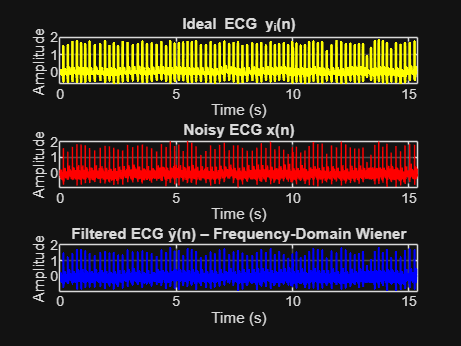


figure;

% Subplot 1 - Ideal ECG
subplot(3,1,1);
plot(t, yi, 'y', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude');
title('Ideal ECG y_i(n)');
grid on;

% Subplot 2 - Noisy ECG
subplot(3,1,2);
plot(t, x, 'r');
xlabel('Time (s)'); ylabel('Amplitude');
title('Noisy ECG x(n)');
grid on;

% Subplot 3 - Filtered ECG
subplot(3,1,3);
plot(t, y_hat, 'b', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Filtered ECG ŷ(n) – Frequency-Domain Wiener');
grid on;